# Lens transmittance 

The lens transmittance has a very large impact on the spectral irradiance at the retina.  The impact of the macular pigment is also shown.

Both of these pigments are normally incorporated in the ISETBio calculation, and the density of each of these pigments can be set.

**See also: **

    t_conesPhotopigment

## Initialize ISETBio

ieInit

## Create a colorful image

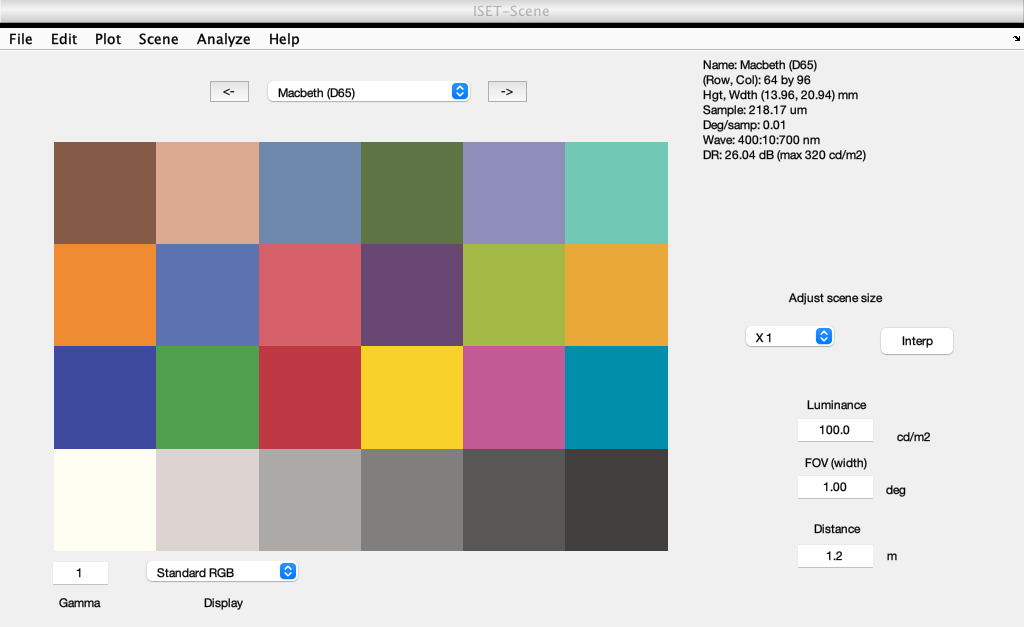

scene = sceneCreate;
scene = sceneSet(scene, 'fov', 1);
ieAddObject(scene); sceneWindow;

## The macular pigment

Here we illustrate the effect of the macular pigment by including the typical lens absoprtance and then multiplying by the macular absorptance. We stick the effect of the two pigments to the optical image calculation.

Create the default optical image with the human lens.

oi = oiCreate();

Make sure the lens density is set to the default and compute.  Not really necessary, but in case you want to change the density, this is how.

oi = oiSet(oi,'lens density',1);
oi = oiCompute(oi, scene);

Get the macular pigment transmittance and apply it to the photons

Mac = Macular;
photons = oiGet(oi,'photons');
[photons, row, col] = RGB2XWFormat(photons);
photons = photons*diag(Mac.transmittance);


Put the modified photons back into the oi.  This is a very yellow image!

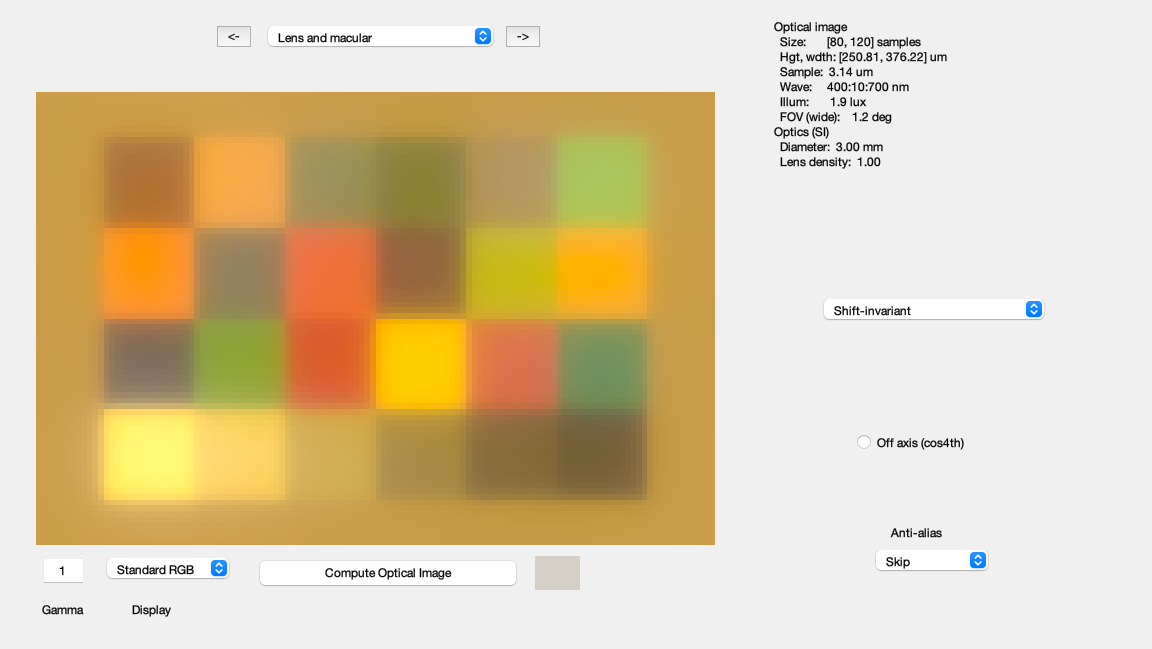

photons = XW2RGBFormat(photons,row,col);
oi = oiSet(oi,'photons',photons);
oi = oiSet(oi,'name','Lens and macular');
ieAddObject(oi); oiWindow;

## The standard WVF optics model without the macular pigment

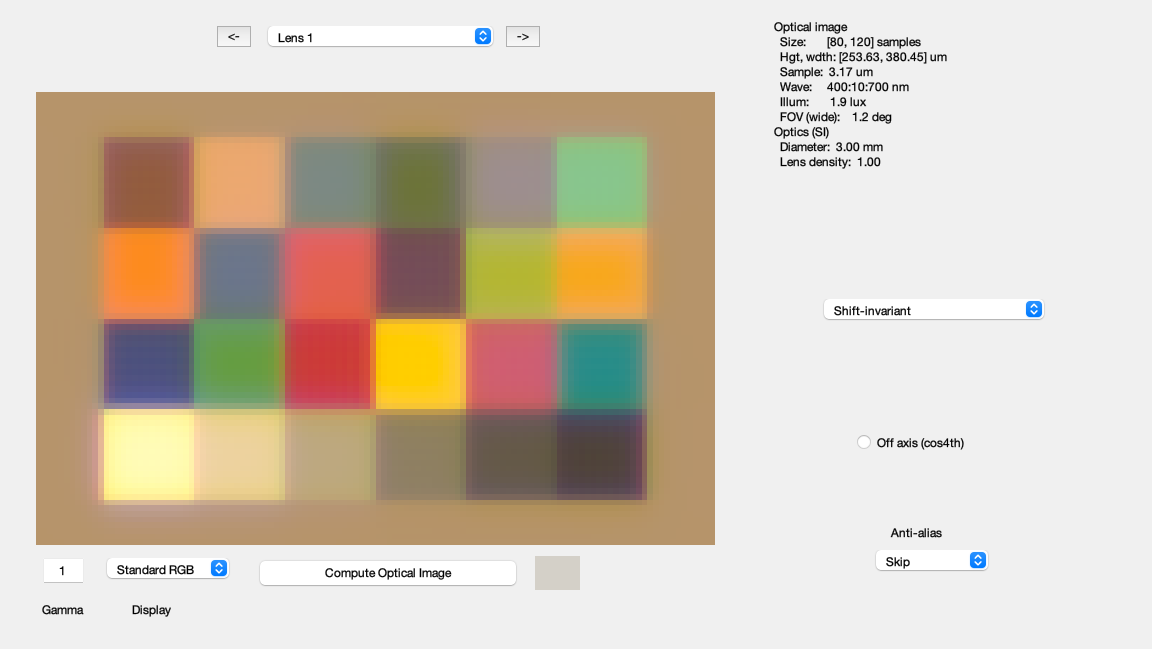

oi = oiCreate('wvf human');
oi = oiCompute(oi, scene);
oi = oiSet(oi,'name','Lens 1');
ieAddObject(oi); oiWindow;

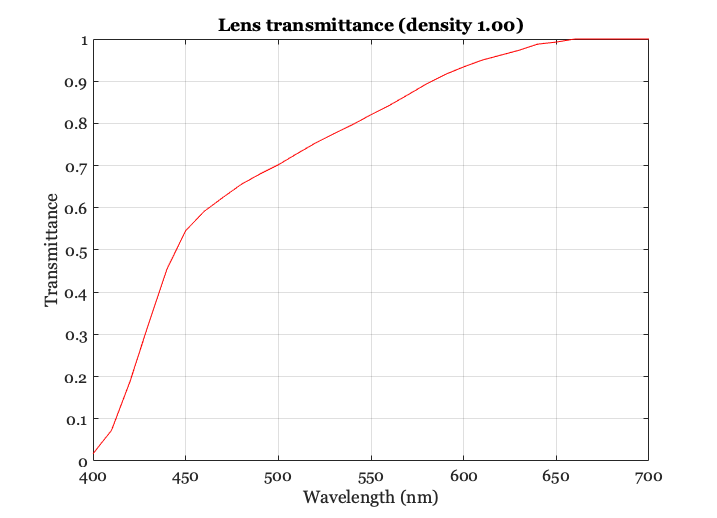

oiPlot(oi, 'lens transmittance');

## Set the lens density to 0.3

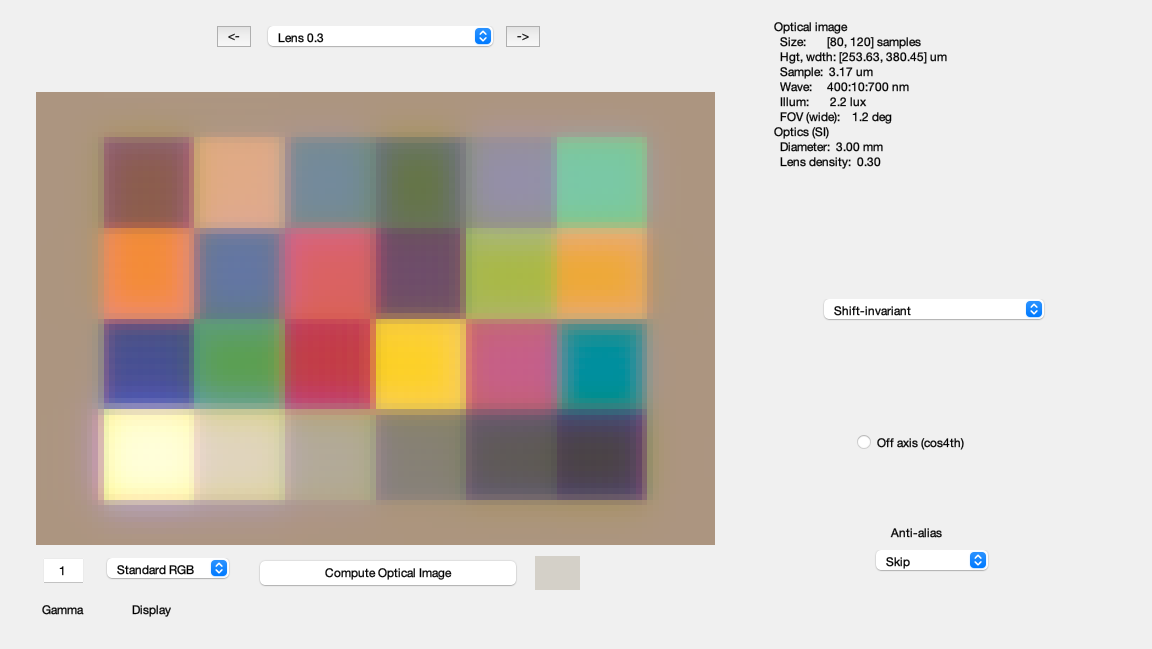

oi = oiSet(oi, 'lens density', 0.3);
oi = oiCompute(oi, scene);
oi = oiSet(oi,'name','Lens 0.3');

ieAddObject(oi); oiWindow;

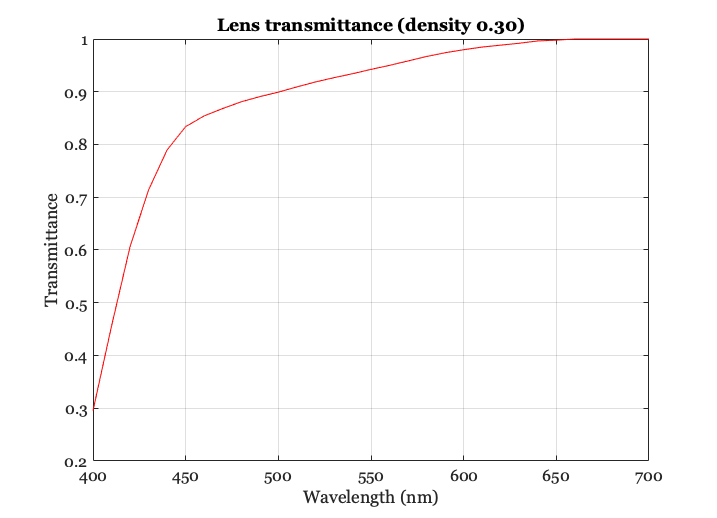

oiPlot(oi, 'lens transmittance');

## Set the lens density to 0

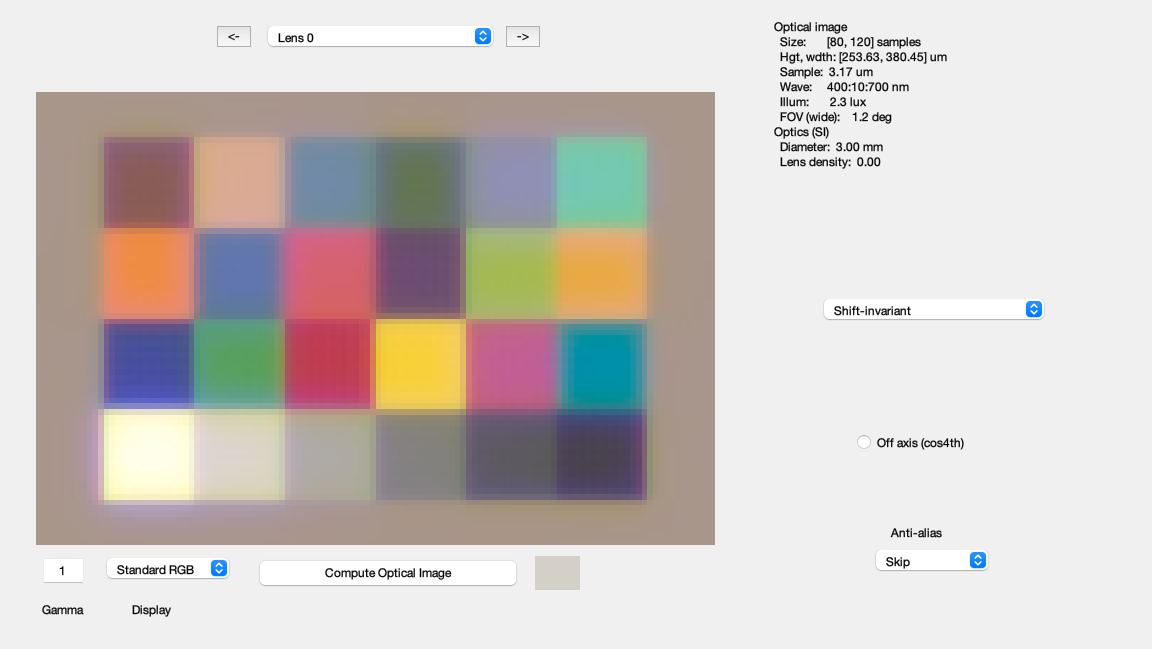

oi = oiSet(oi, 'lens density', 0);
oi = oiCompute(oi, scene);
oi = oiSet(oi,'name','Lens 0');
ieAddObject(oi); oiWindow;

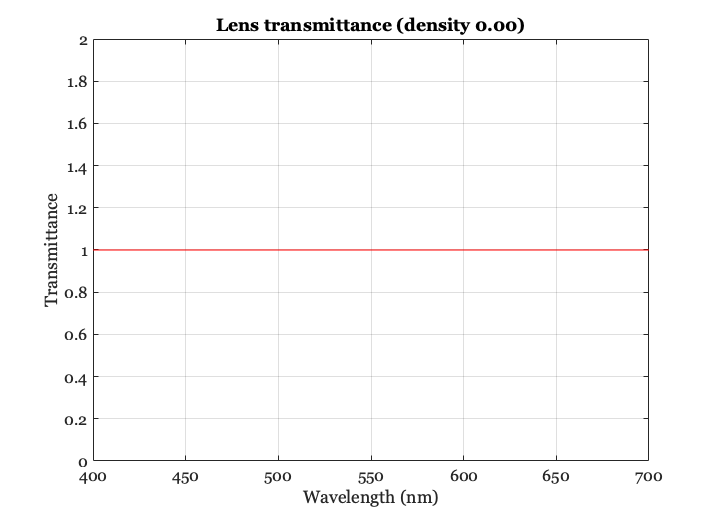

oiPlot(oi, 'lens transmittance');